clc;
clear;
close all;

% Define the paths to the training and testing datasets
train_dir = 'C:\Users\nexti\Downloads\maheen\Train';
test_dir = 'C:\Users\nexti\Downloads\maheen\Test';

% Preprocess images in the training directory
preprocessImages(train_dir);

Processing images in D:\cep ml\waleed\waleed saif\Train\Dent...
Processed images in D:\cep ml\waleed\waleed saif\Train\Dent
Processing images in D:\cep ml\waleed\waleed saif\Train\Scratch...
Processed images in D:\cep ml\waleed\waleed saif\Train\Scratch
Processing images in D:\cep ml\waleed\waleed saif\Train\Spot...
Processed images in D:\cep ml\waleed\waleed saif\Train\Spot



% Preprocess images in the testing directory
preprocessImages(test_dir);

Processing images in D:\cep ml\waleed\waleed saif\test\Dent...
Processed images in D:\cep ml\waleed\waleed saif\test\Dent
Processing images in D:\cep ml\waleed\waleed saif\test\Scratch...
Processed images in D:\cep ml\waleed\waleed saif\test\Scratch
Processing images in D:\cep ml\waleed\waleed saif\test\Spot...
Processed images in D:\cep ml\waleed\waleed saif\test\Spot



disp('Preprocessing completed.');

Preprocessing completed.



% Define batch size
batch_size = 32;

% Data augmentation
imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-15, 15], ...
    'RandXReflection',true, ...
    'RandYReflection',true, ...
    'RandXScale',[0.9 1.1], ...
    'RandYScale',[0.9 1.1], ...
    'RandYShear',[-10 10], ...
    'RandXShear',[-10 10], ...
    'RandXTranslation',[-5 5], ...  
    'RandYTranslation',[-5 5]);   

% Define the target dimensions for the augmented images
img_height = 256;
img_width = 256;

% Read training images
trainData = imageDatastore(train_dir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Apply data augmentation to training images
augmentedTrainData = augmentedImageDatastore([img_height img_width 3], trainData, 'DataAugmentation', imageAugmenter, 'ColorPreprocessing', 'gray2rgb');

% Read test images
testData = imageDatastore(test_dir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Create an augmented image datastore for the test data
augmentedTestData = augmentedImageDatastore([img_height img_width 3], testData, 'DataAugmentation', imageAugmenter, 'ColorPreprocessing', 'gray2rgb');

% Define the number of classes based on the subfolders in the training dataset
num_classes = 3; % normal, Dents, Scratches, Spots


% Define the CNN architecture
layers = [
    imageInputLayer([img_height img_width 3]) % Input layer expects RGB images (3 channels)
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(256)
    reluLayer
    
    fullyConnectedLayer(3) % Adjusted for the correct number of classes (3 in this case)
    softmaxLayer % Using softmax activation for multi-class classification
    classificationLayer]; % Specify classification layer for multi-class classification


Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:06 |       34.38% |       33.33% |       2.1253 |      10.6283 |          0.0010 |


|       3 |          10 |       00:00:32 |       34.38% |       42.03% |       7.0063 |       4.3041 |          0.0010 |


|       5 |          20 |       00:00:59 |       28.13% |       53.62% |       3.5189 |       2.4875 |          0.0010 |


|       8 |          30 |       00:01:37 |       37.50% |       49.28% |       1.9059 |       1.7002 |          0.0010 |


|      10 |          40 |       00:02:22 |       59.38% |       46.38% |       1.0878 |       1.7342 |          0.0010 |


|      13 |          50 |       00:02:46 |       65.63% |       47.83% |       1.0117 |       2.4749 |          0.0010 |


|      15 |          60 |       00:03:07 |       62.50% |       46.38% |       0.8636 |       1.2809 |          0.0010 |


|      18 |          70 |       00:03:29 |       46.88% |       56.52% |       1.6757 |       1.3707 |          0.0010 |


|      20 |          80 |       00:04:12 |       62.50% |       56.52% |       1.1995 |       1.2535 |          0.0010 |


|======================================================================================================================|


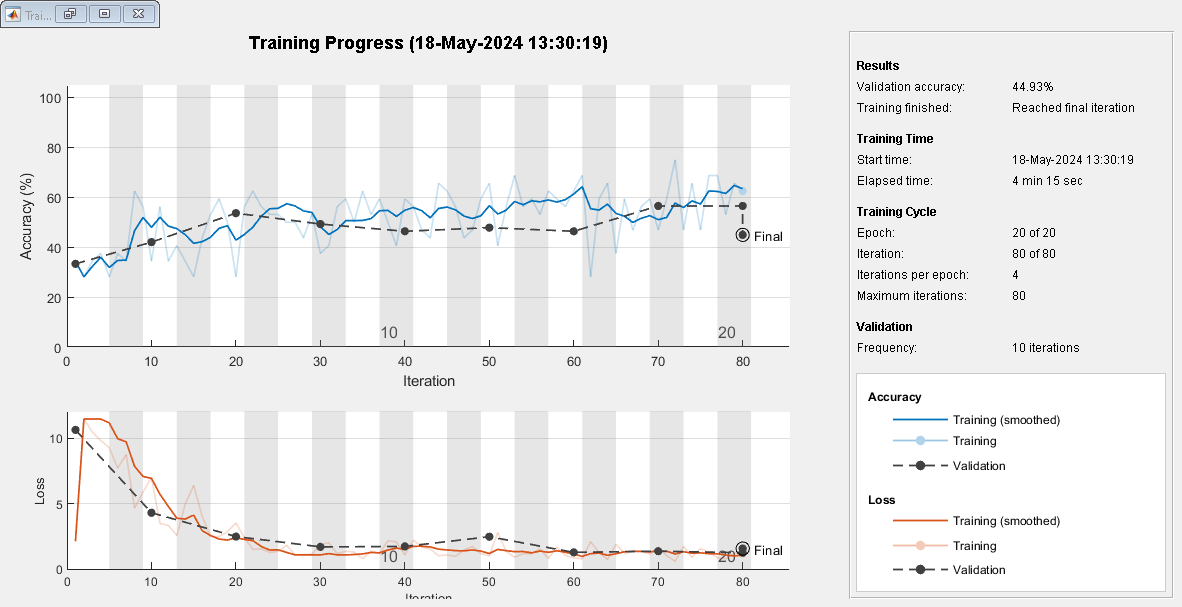

net =   SeriesNetwork with properties:

         Layers: [18×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}



% Define training options
options = trainingOptions('adam',...
    'MiniBatchSize', batch_size,...
    'MaxEpochs', 20,...
    'InitialLearnRate', 1e-3,...
    'Shuffle', 'every-epoch',...
    'ValidationData', augmentedTestData,...
    'ValidationFrequency', 10,...
    'Verbose', true,...
    'Plots', 'training-progress');

% Train the CNN
   net = trainNetwork(augmentedTrainData, layers, options)

   

save('D:\cep ml\mlcepsave', 'net');



% Load the trained model
try
    load('D:\cep ml\mlcepsave', 'net');
catch
    error('Failed to load the trained model. Make sure the file exists and is accessible.');
end

% Prompt the user to select an image file to predict
[filename, folder_path] = uigetfile('*.png', 'Select an image file to predict');
if filename == 0
    disp('User canceled the operation');
    return; % Exit the script if the user cancels the operation
end

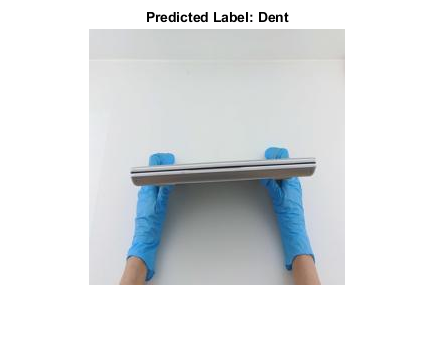


% Combine the folder path and filename to get the full image path
image_path = fullfile(folder_path, filename);

% Check if the image file exists
if ~exist(image_path, 'file')
    error('The selected image file does not exist.');
end

% Read the image
input_image = imread(image_path);

% Resize the image to match the expected input size of the network
input_image = imresize(input_image, [256 256]);

% Check if the image has 3 channels, if not, convert to RGB
if size(input_image, 3) ~= 3
    input_image = cat(3, input_image, input_image, input_image); % Convert to RGB
end

% Predict the label of the image using the trained network net
predicted_label = classify(net, input_image);

% Display the image and its prediction
figure;
imshow(input_image);
title(['Predicted Label: ', char(predicted_label)]);


% Pause for a few seconds to allow the user to see the image and its prediction
pause(1); % Adjust the pause time as desired

% Function to resize images and convert them to RGB


function preprocessImages(directory)
    % Loop through subfolders
    subfolders = dir(directory);
    for i = 1:numel(subfolders)
        if subfolders(i).isdir && ~strcmp(subfolders(i).name, '.') && ~strcmp(subfolders(i).name, '..')
            subfolder = fullfile(directory, subfolders(i).name);
            fprintf('Processing images in %s...\n', subfolder);
            
            % Loop through images in the subfolder
            imageFiles = dir(fullfile(subfolder, '*.jpg'));
            for j = 1:numel(imageFiles)
                filename = fullfile(subfolder, imageFiles(j).name);
                
                % Read the image
                img = imread(filename);
                
                if ~isempty(img)
                    % Resize the image to a fixed height and width
                    img_resized = imresize(img, [256, 256]);
                    
                    % Check if the image is grayscale
                    if size(img_resized, 3) == 1
                        % Convert grayscale image to RGB by duplicating the grayscale channel across all three channels
                        img_rgb = cat(3, img_resized, img_resized, img_resized);
                    else
                        % Image is already RGB
                        img_rgb = img_resized;
                    end
                    
                    % Save the processed image
                    imwrite(img_rgb, filename);
                end
            end
            fprintf('Processed images in %s\n', subfolder);
        end
    end
end